# Analisando a transformada de Laplace

clear all;
clc;
close all;


## Analisando um circuito RC primeira ordem

$G(s)=\frac{1}{s+1}
$ um sistema de primeira ordem

Grc = tf(1,[1 1])

Grc =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



## Resposta Impulsiva

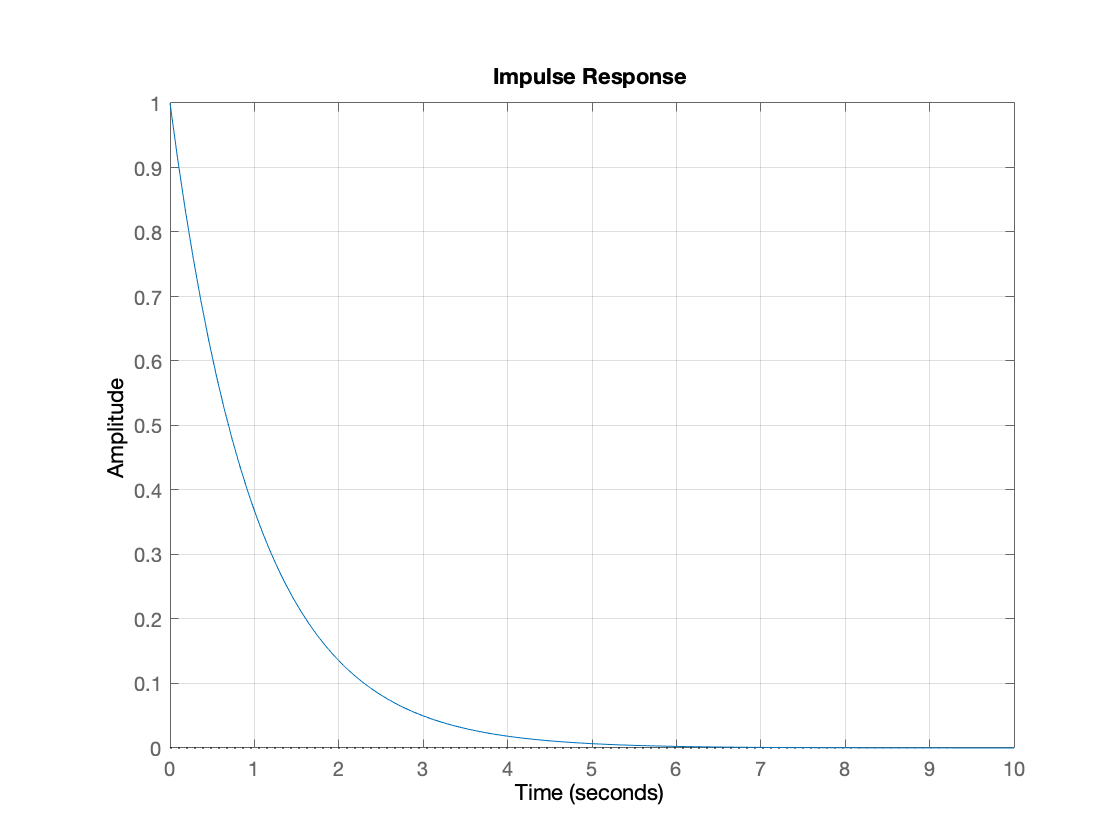


impulse (Grc,10);       % reposta impulsiva
grid;

## Resposta ao degrau

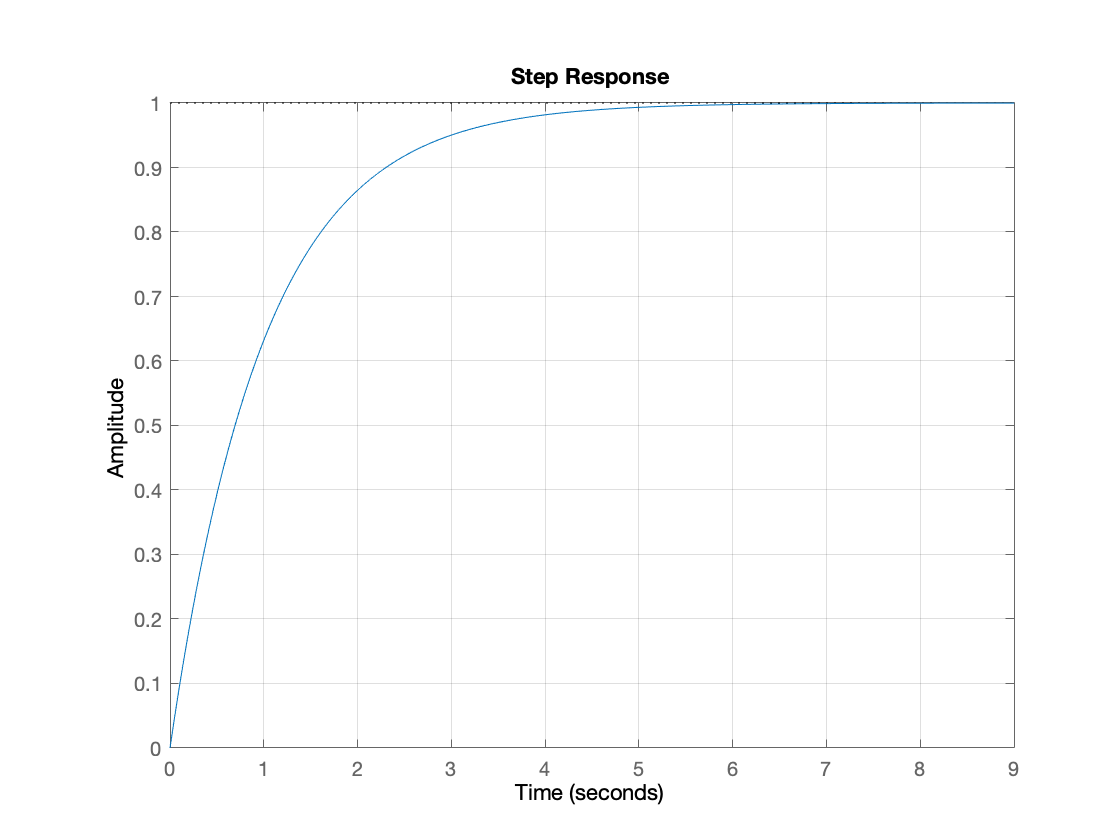


step(Grc);          % resposta ao degrau
grid;

## Aplicando um sinal harmônico no sistema - RC

tempo = linspace(0,10,1000);           % defini o vetor tempo
w1    = 5*pi;                         % frequência do sinal
x1     = sin(w1*tempo);                % entrada do sistema
w2    = 2*pi;                          % frequência do sinal
x2     = sin(w2*tempo);                % entrada do sistema

[y1,t1] = lsim(Grc,x1,tempo);                % saída do sistema
[y2,t2] = lsim(Grc,x2,tempo);                % saída do sistema

figure(2)
subplot(2,2,1);                        % entrada
plot(tempo,x1);
title('Entrada do sistema');
xlabel('tempo em segundos');
ylabel('mplitude em volts');
grid;

subplot(2,2,2);                        % saída
plot(tempo,y1,"linewidth",2);
title('Saída do sistema');
xlabel('tempo em segundos');
ylabel('mplitude em volts');
grid;
hold;

Current plot held


yyaxis right
impulse(Grc)


subplot(2,2,3);                        % entrada
plot(tempo,x2);
title('Entrada do sistema');
xlabel('tempo em segundos');
ylabel('mplitude em volts');
grid;


subplot(2,2,4);                        % saída
plot(tempo,y2,"linewidth",2);
title('saída do sistema');
xlabel('tempo em segundos');
ylabel('mplitude em volts');
grid;
hold;

Current plot held


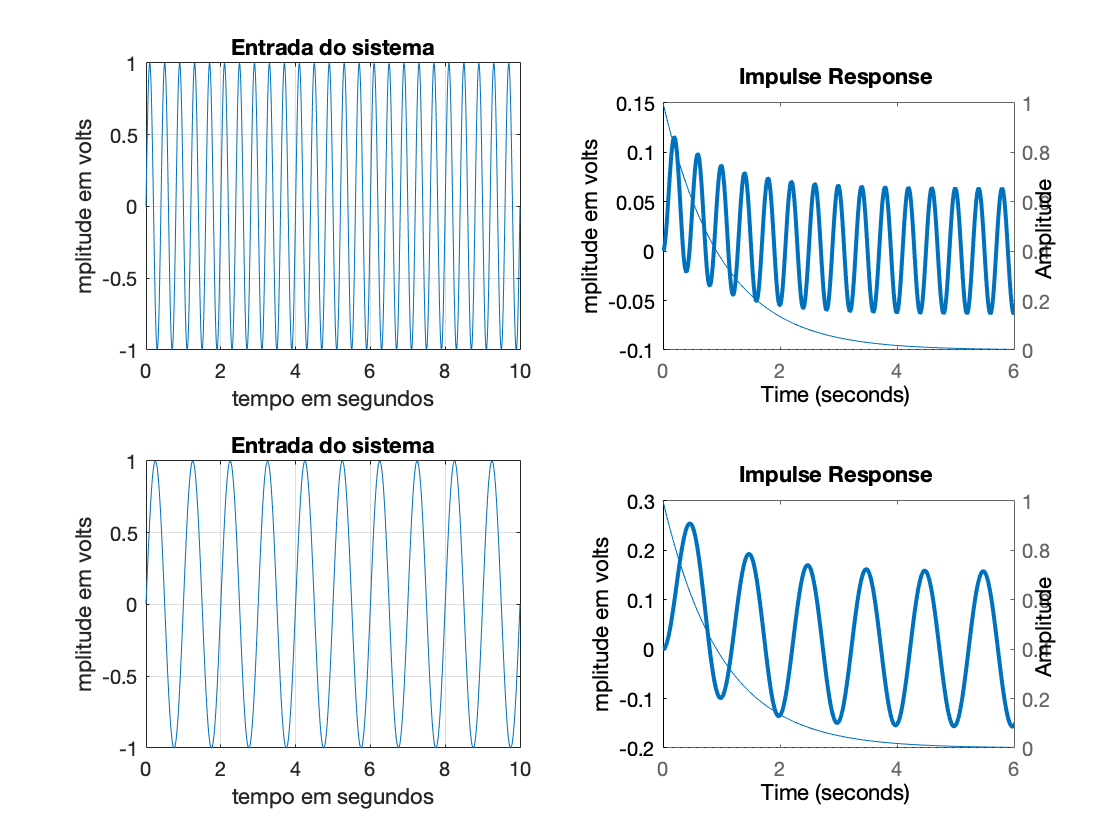

yyaxis right
impulse(Grc)

## Determinando o tempo em que o sistema converge

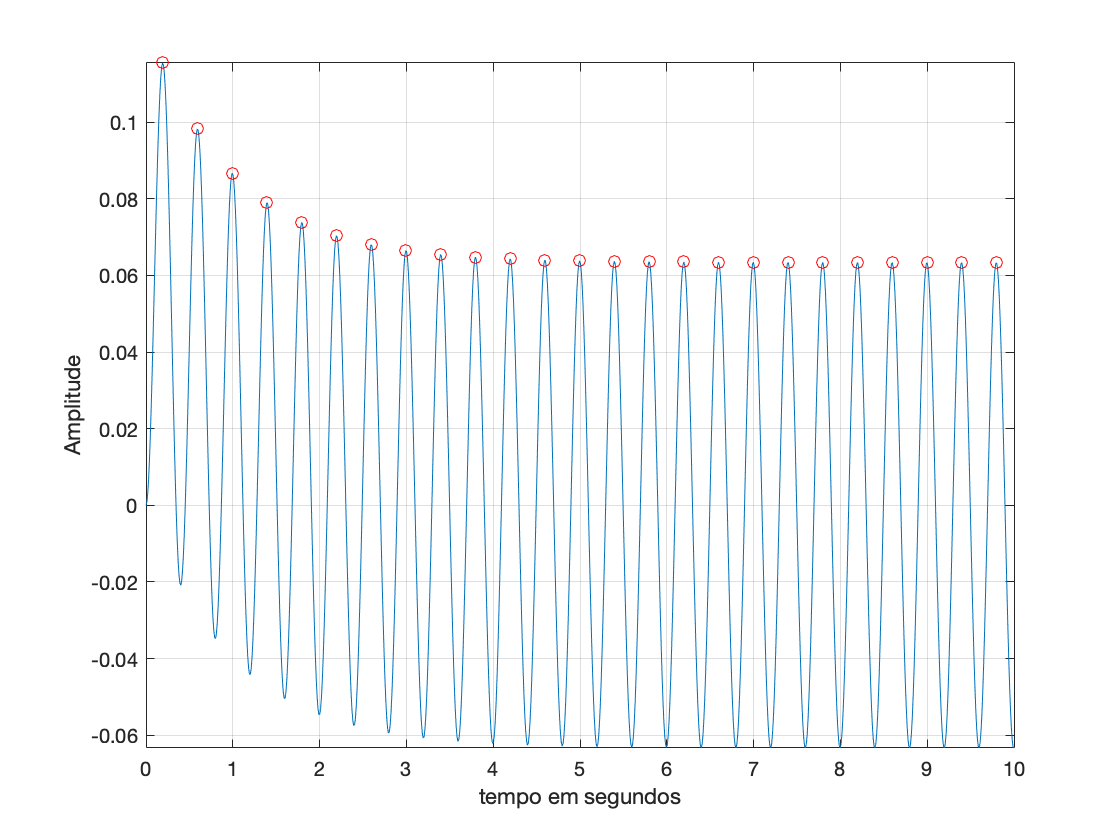


[pks1,locs1] = findpeaks(y1);
[pks2,locs2] = findpeaks(y2);

figure(3)

plot(t1,y1,t1(locs1),pks1,'or')
xlabel('tempo em segundos')
ylabel('Amplitude')
axis tight;
grid;

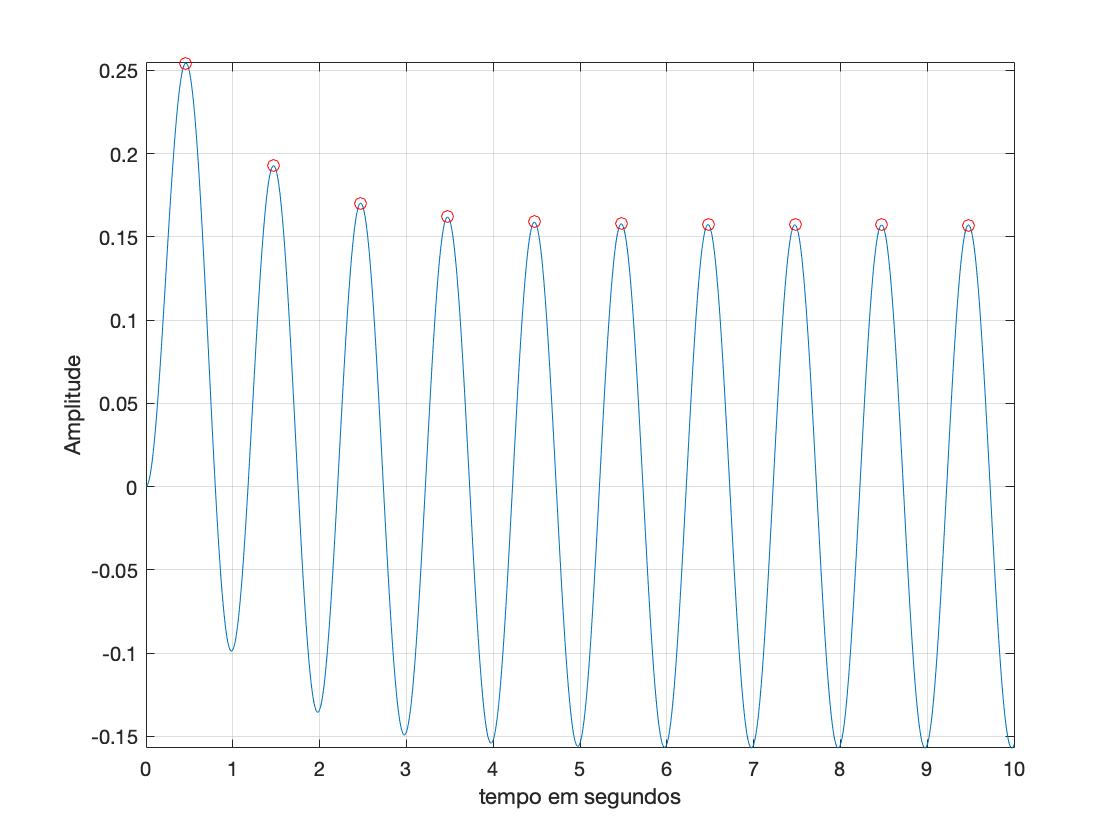


figure(4)

plot(t2,y2,t2(locs2),pks2,'or')
xlabel('tempo em segundos')
ylabel('Amplitude')
axis tight;
grid;

## Ajustando os dados a uma exponencial

f = fit(t1(locs1),y1(locs1)-y1(locs1(end)),'exp1')

f =      General model Exp1:
     f(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =     0.06301  (0.06281, 0.06321)
       b =     -0.9974  (-1.002, -0.9929)

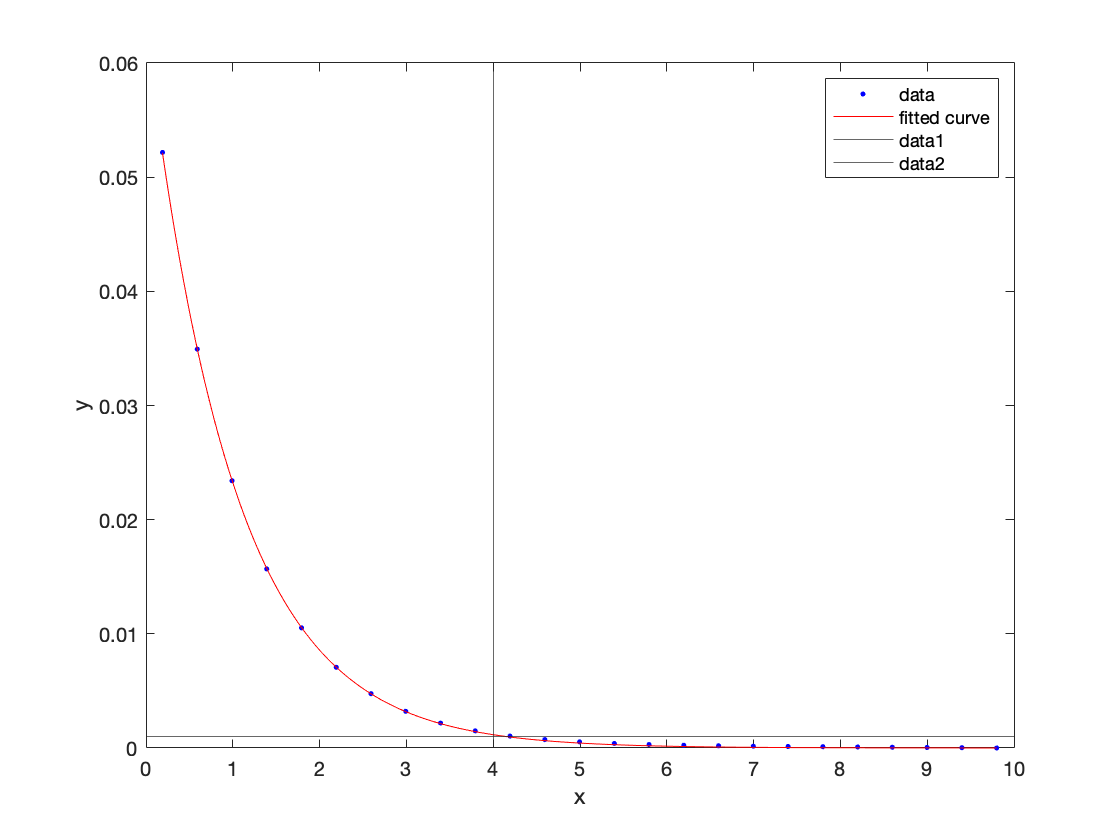


plot(f,t1(locs1),y1(locs1)-y1(locs1(end)))
xline(4)
delta1 = (y1(locs1(1))-y1(locs1(end)));
delta1 = delta1 - 0.98*delta1;
yline(delta1)

## Analisando o segundo gráfico

f = fit(t2(locs2),y2(locs2)-y2(locs2(end)),'exp1')

f =      General model Exp1:
     f(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =      0.1538  (0.1536, 0.154)
       b =     -0.9939  (-0.9954, -0.9924)

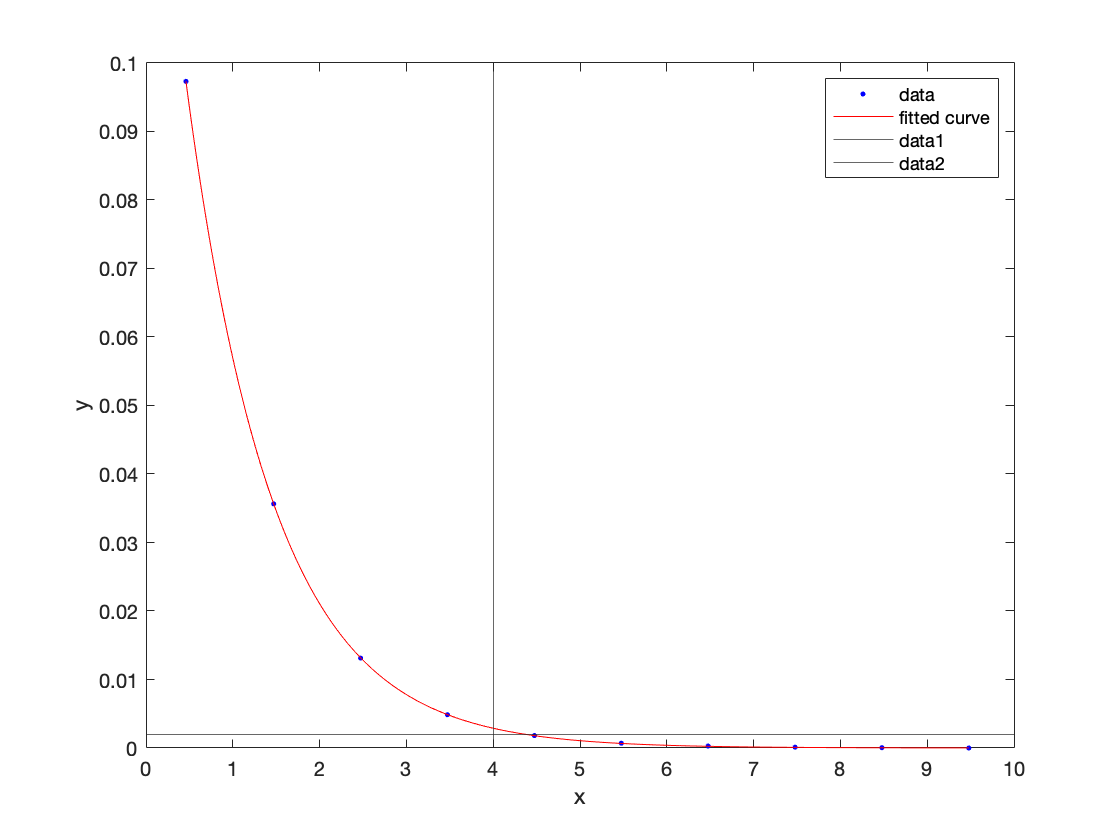


plot(f,t2(locs2),y2(locs2)-y2(locs2(end)))
xline(4)
delta2 = (y2(locs2(1))-y2(locs2(end)));
delta2 = delta2 - 0.98*delta2;
yline(delta2)

## Analisando a forma canônica

Sabemos que a forma canônica é dada por:


$$G(s) = \frac{w_n^2}{s^2+2\zeta\omega_ns+w_n^2}
$$


No caso do circuito RLC que estudamos temos:


$$G(s) = \frac{\frac{1}{LC}}{s^2+2\frac{R}{L}s+\frac{1}{LC}}}
$$


## Definindo as função de transferência

N  = (2*pi)^2;

Amortecimento nulo - $\zeta = 1
$

D1 = [1 0 (2*pi)^2];

Tempo de convergência de 4 segundos - $\zeta \omega_n=1$

D2 = [1 2 (2*pi)^2];

Pólos iguais com amortecimento  - $\zeta = 1
$

D3 = [1 2*2*pi (2*pi)^2];


## Sistemas

G1 = tf(N,D1)

G1 =
 
     39.48
  -----------
  s^2 + 39.48
 
Continuous-time transfer function.



G2 = tf(N,D2)

G2 =
 
        39.48
  -----------------
  s^2 + 2 s + 39.48
 
Continuous-time transfer function.



G3 = tf(N,D3)

G3 =
 
          39.48
  ---------------------
  s^2 + 12.57 s + 39.48
 
Continuous-time transfer function.



## Resposta dos sistemas ao impulso

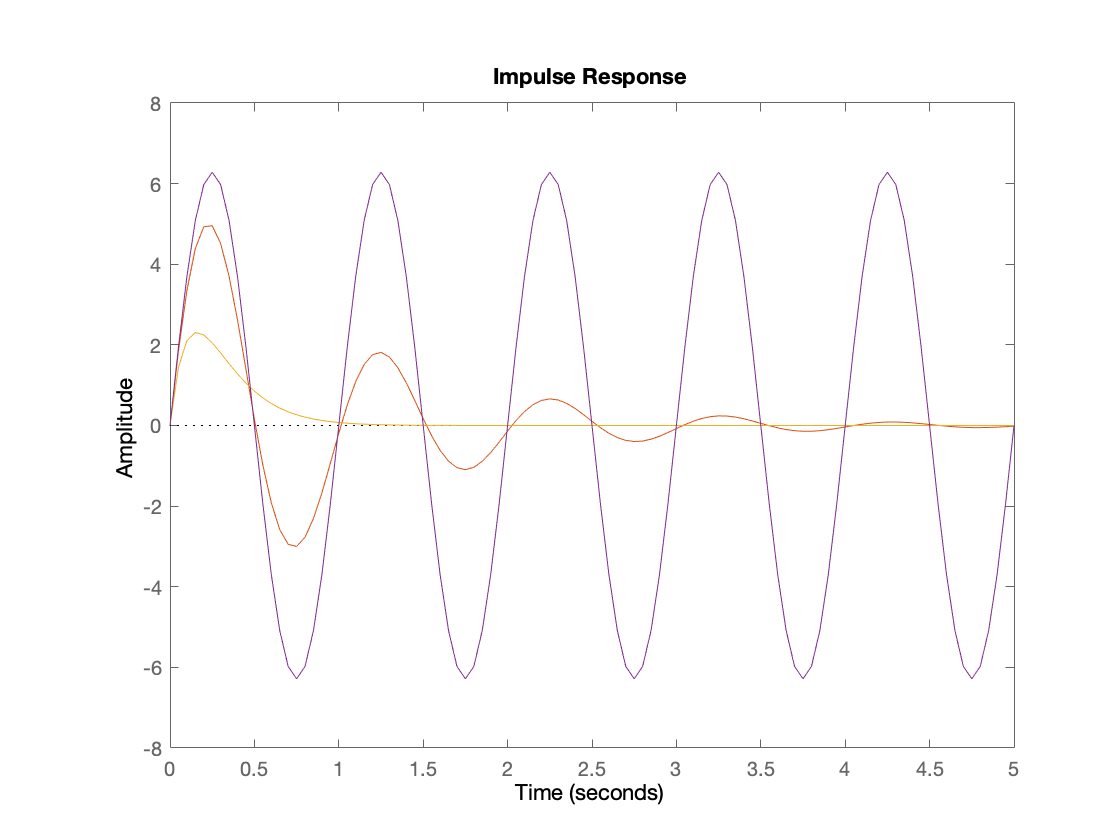

Current plot released


impulse(G1,5); 
hold

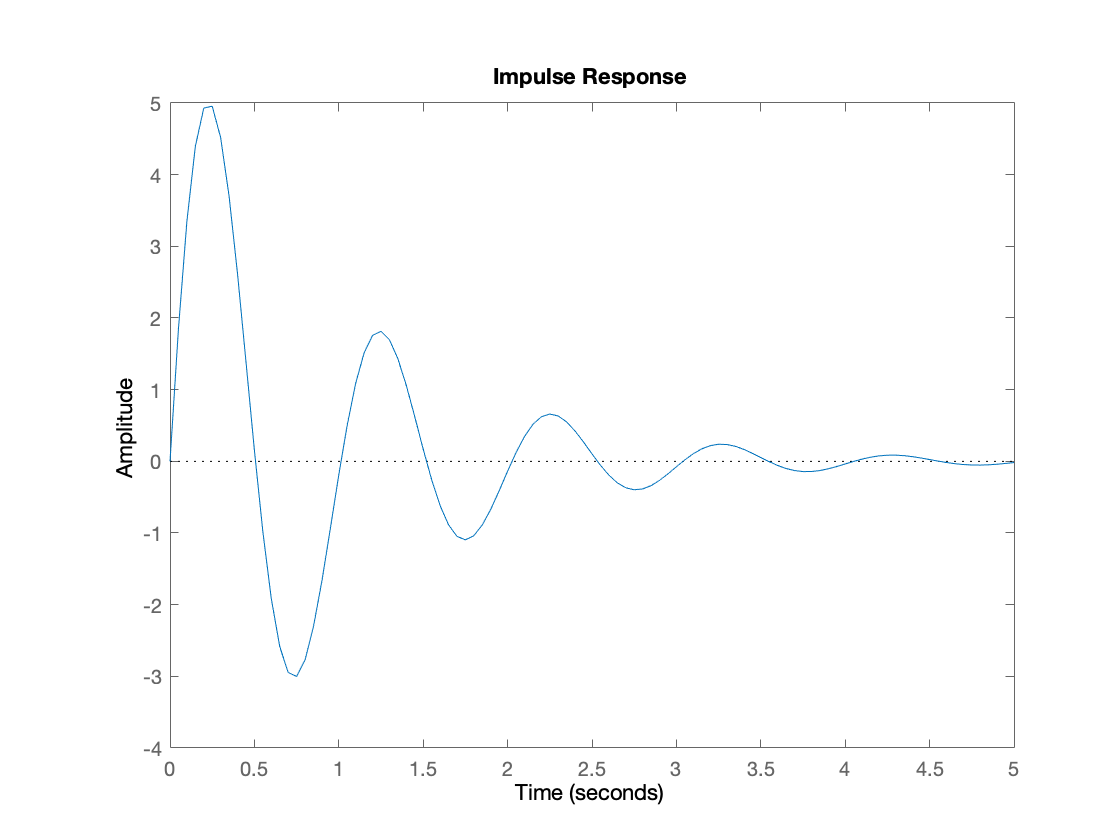

impulse(G2,5);

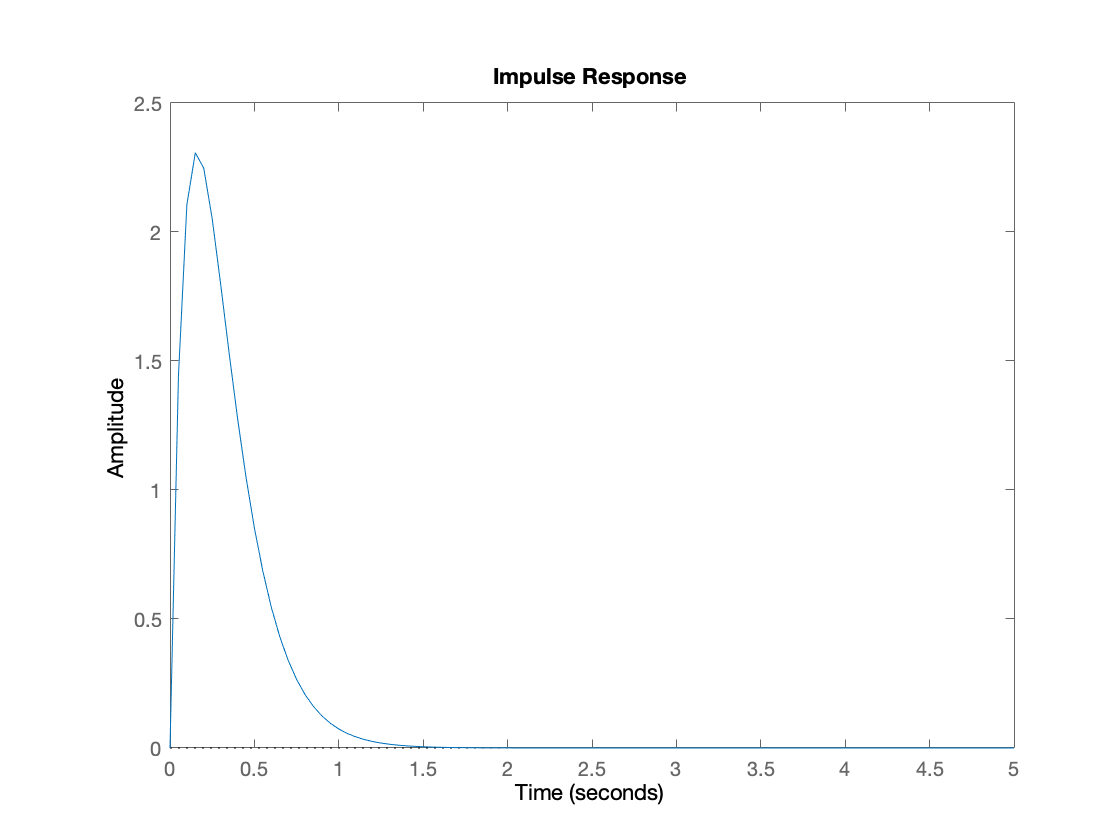

impulse(G3,5);

## Resposta dos sistemas ao degrau

step(G1,5); 
hold

Current plot held


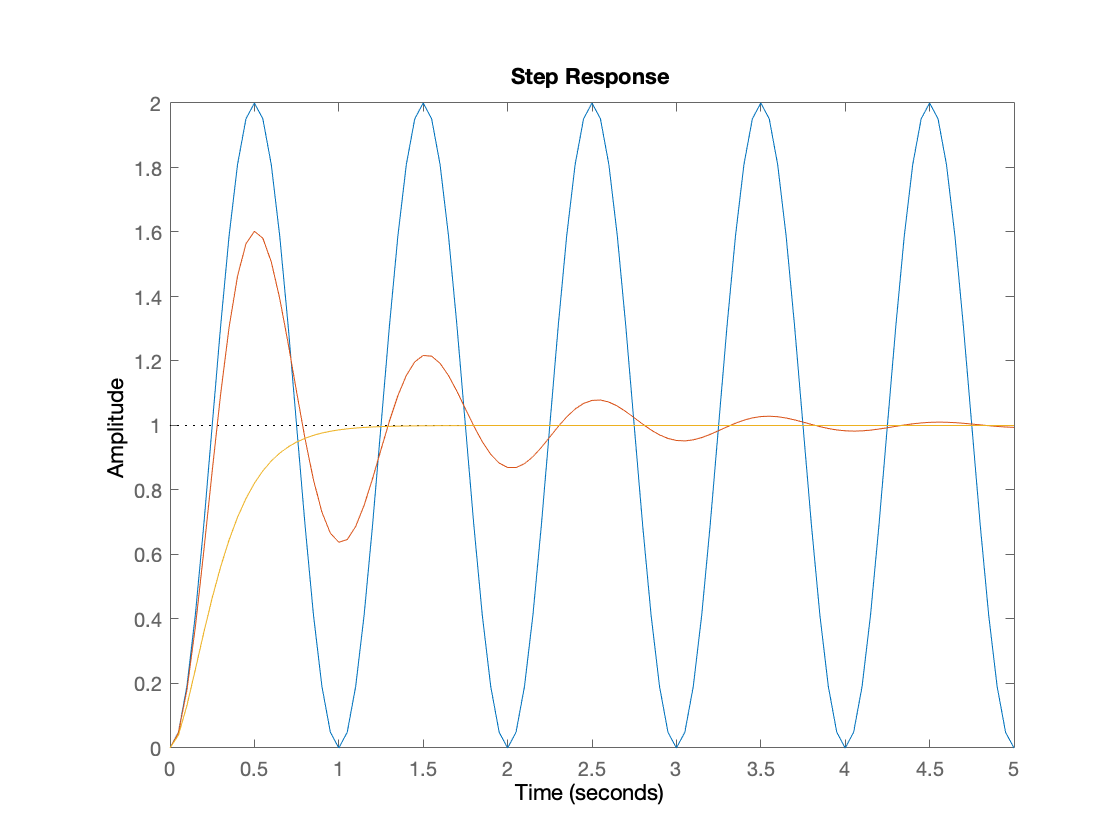

step(G2,5);
step(G3,5);